# Problema 2 - Suplimentara

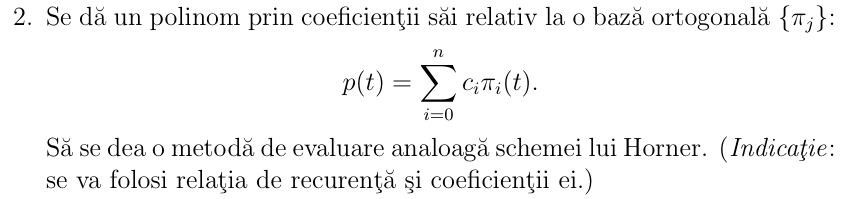

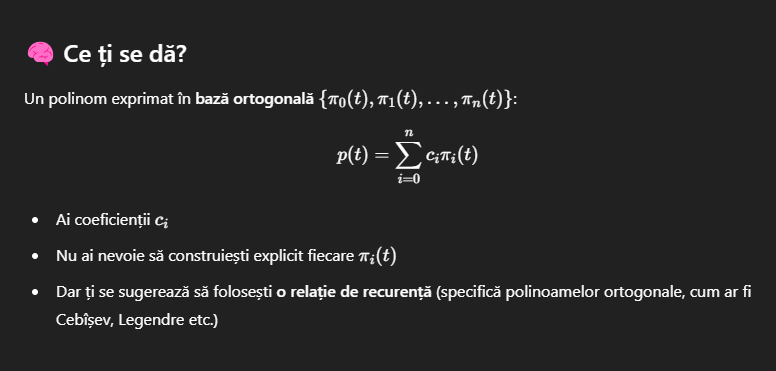

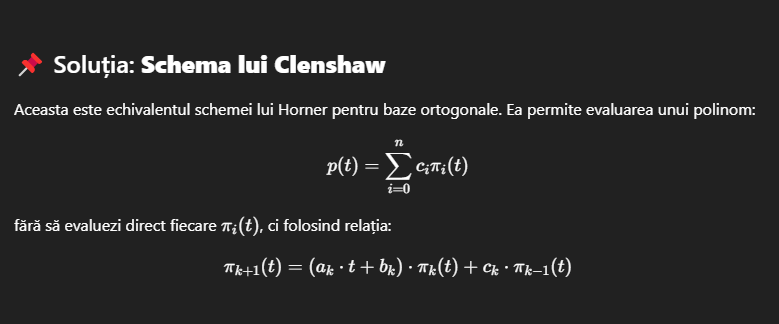

function val = horner_ortogonal(t0, c, basis)
    % Evaluare p(t0) 
    % folosind recurenta bazei ortogonale (ex: Cebisev)
    
    n = length(c) - 1;
    b = zeros(n + 3, 1);  

    switch basis
        case 'chebyshev'
            % Coeficienti 
            a = 2; % constant
            for k = n:-1:0
                b(k+1) = a * t0 * b(k+2) - b(k+3) + c(k+1);
            end
            val = b(1);
        otherwise
            error('Baza ortogonala necunoscuta.');
    end
end

c = [1 2 3];
x = 0.5;

% Evaluare clasica
T0 = 1;
T1 = x;
T2 = 2*x*T1 - T0;
p_direct = c(1)*T0 + c(2)*T1 + c(3)*T2;

% Evaluare cu schema lui Horner ortogonal
p_horner = horner_ortogonal(x, c, 'chebyshev');

fprintf('Evaluare directă: %.4f\n', p_direct);

Evaluare directă: 0.5000


fprintf('Evaluare Horner ortogonal: %.4f\n', p_horner);

Evaluare Horner ortogonal: 3.0000
